# Linear Control Design II - Group Work Problem Module 9

## **Description**

The dynamics of a wind turbine operating in the full load region reads

$J_r\dot{\omega}_r = \frac{1}{2}\rho A R \mathrm{CP}(\beta,\lambda) \frac{v^2}{\lambda} - K_{d}\theta - B_{d}\left(\omega_r - \frac{\omega_g}{N_g}\right)$       (1)

$J_g\dot{\omega}_g = \frac{K_{d}}{N_g}\theta + \frac{B_{d}}{N_g}\left(\omega_r - \frac{\omega_g}{N_g}\right) - T_g$       (2)

$\dot{\theta} = \omega_r - \frac{\omega_g}{N_g}$       (3)

$y_1 = \omega_r$       (4)

$y_2 = P_e = \omega_g T_g$       (5)

where all quantities of interest are defined Group work Module 1. Based on the provided Simulink model '*OpenLoopWindTurbineModel.slx*' and on the system parameter file 'OpenLoopWindTurbine_Parameters.mat' address the following problems.

## Problems

**P1    **Set the operating wind speed $v_{OP} = 20\,\mathrm{m/s}$ and compute analytically as well as numerically the operating point for the state vector $\mathbf{x}_{OP} = \left[\omega_{r,OP},\omega_{g,OP},\theta_{OP}\right]^\mathrm{T}$ and the input vector $\mathbf{u}_{OP} = \left[\beta_{OP},T_{g,OP}\right]^\mathrm{T}$.

**P1.Solution**

Let us derive the operating point analiticaly. Five unknowns have to be determined including the input and the state vector in order to fully determine the operating point. As known from GroupWork module 1 the wind speed defines the range the Turbine is operating in. $v_{OP} = 20\,\mathrm{m/s}$ implies that the turbine is operating in the full load region fixing both $P_e$, the generated power in [MW] and $\omega_r$, the rotor speed [rad/s] as


$$P_{e,OP}
 = 5 \ mW$$



$$\omega_{r,OP} = 1.2671 \ rad/s$$


At the operating point $\mathbf{\dot{x}}_{OP} = \left[\dot{\omega}_{r,OP},\dot{\omega}_{g,OP},\dot{\theta}_{OP}\right]^\mathrm{T} = 0$. From (3) it follows

$\omega_{g,OP} = \omega_{r,OP}\cdot N_g$       (6)

From (5) 

$T_{g,OP} = \frac{P_{e,OP}}{\omega_{g,OP}} $       (7)

Substituting (3) in to (2) and (1) simplifies the expressions and lead to

$\theta_{OP} = T_{g,OP}\frac{N_g}{K_d}$       (8)

$ \mathrm{CP}(\beta_{OP},\lambda_{OP})  = 2\frac{K_{d}}{\rho A R}\frac{\lambda_{OP}}{v^2}\theta_{OP}$       (9)

(9) is a non linear equation that can be used to find $\beta_{OP}$ knowing $CP$ at the operating point. $CP$ is in fact known because $\lambda_{OP}$ is also known. In fact

$\lambda_{OP} = \frac{\omega_{r,OP}\cdot R}{v_{OP}}$       (10)

(9) depends only on $\beta_{OP}$ then. 

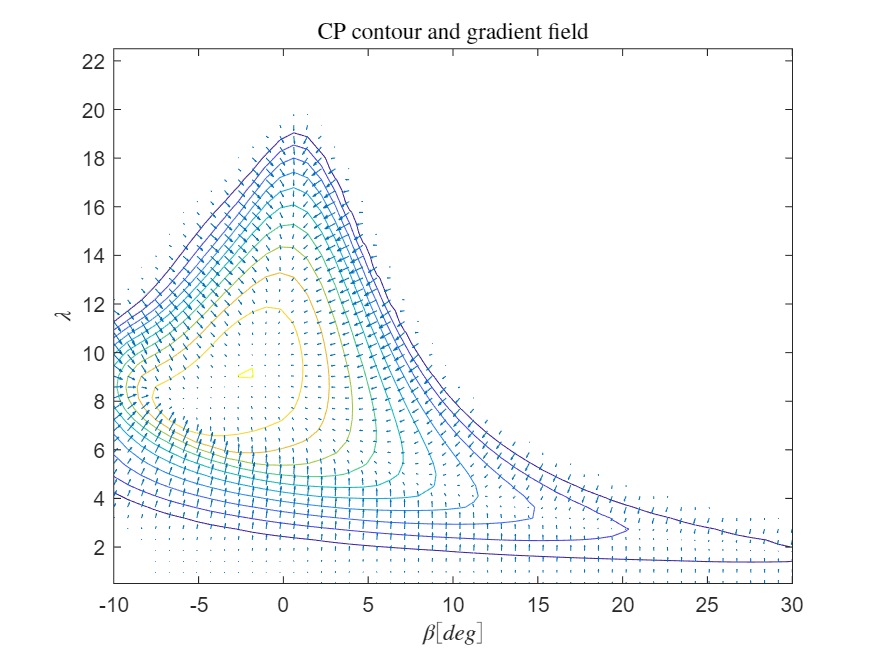

clear
close all
clc

% Analytical Derivation
load('OpenLoopWindTurbine_Parameters.mat')

% Display the CP function contour plot and gradient field, just to visualize it.
[dCpBeta, dCpLambda] = gradient(CP);

figure(1)
contour(Pitch,Lambda,CP)
hold on
quiver(Pitch,Lambda,dCpBeta,dCpLambda)
xlabel('$\beta [deg]$','Interpreter','latex')
ylabel('$\lambda$','Interpreter','latex')
title('CP contour and gradient field','Interpreter','latex')
hold off

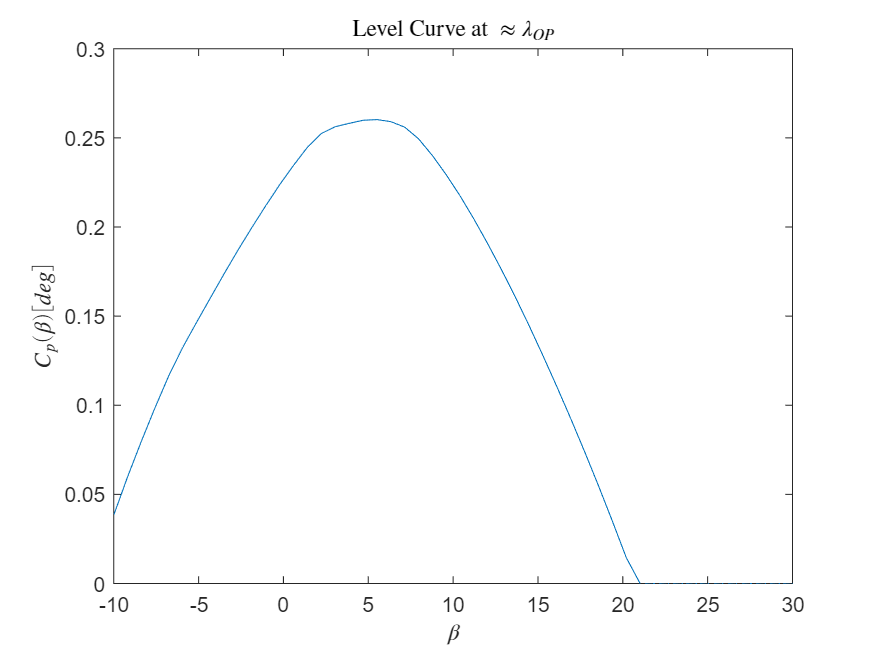


% Following the equations above one finds all the unknowns but beta
v_OP = 20;  %[m/s]
omega_r_OP = 1.2671; %[rad/s]
Pe_OP = 5e6; %[W]

omega_g_OP = Ng*omega_r_OP;
Tg_OP = Pe_OP/omega_g_OP;
theta_Op = Tg_OP*Ng/Kd;

% Analytically only an aproximate beta can be found
LBD_OP = R*omega_r_OP/v_OP;
Diff = Lambda0-LBD_OP;  % Find the closest lambda to the operating point value;
[~,Index_LBD_OP] = min(abs(Diff));  % Find the corresponding index;
CP_fun_beta = CP0(Index_LBD_OP,:); % Find the corresponding CP values given lambda OP.

figure(2)
plot(Pitch0,CP_fun_beta)
xlabel('$\beta$','interpreter','latex')
ylabel('$C_p(\beta) [deg]$','interpreter','latex')
title('Level Curve at $\approx \lambda_{OP}$','Interpreter','latex')

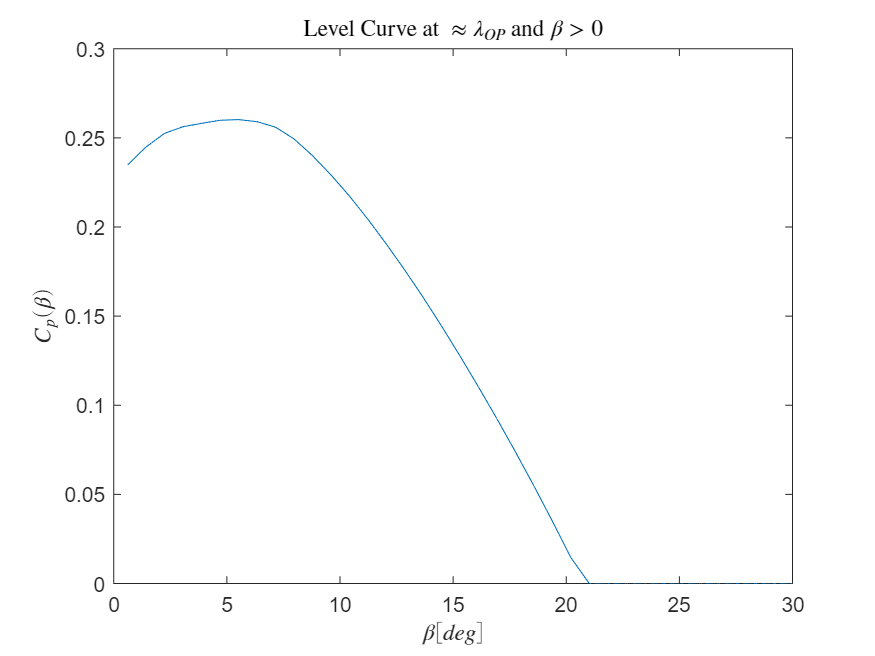


% Exclude CP values corresponding to negative beta. There the turbine is stalled.
i_beta_pos = Pitch0>0; % Logical vector. 1 if Beta >0. 0 elsewhere

figure(3)
plot(Pitch0(i_beta_pos),CP_fun_beta(i_beta_pos))
title('Level Curve at $\approx \lambda_{OP}$ and $\beta > 0$','Interpreter','latex')
xlabel('$\beta [deg]$','interpreter','latex')
ylabel('$C_p(\beta)$','interpreter','latex')


CP_OP_value = 2*omega_r_OP*Ng/(rho_air*A*v_OP^3)*Tg_OP; % CP value at the operating point. See (9)
Diff1 = CP_fun_beta(i_beta_pos)-CP_OP_value; % Find the closest CP to operating point.
[~,Index_Beta_OP] = min(abs(Diff1)); % Find the corresponding index
one = find(i_beta_pos == 1); % Find the first positive bete index.
Beta_OP_deg = Pitch0(one(1)+Index_Beta_OP) % [Deg]

Beta_OP_deg =        18.571


Beta_OP_rad = Beta_OP_deg*pi/180 % [rad]

Beta_OP_rad =       0.32413


So far the operating point is not exactly determined because of $\beta_{OP}$. To exactly determine the operating point one has to trim the system. *trim() *inputs are

- Simulink model to trim;

- inital guesses for $x_{OP}$, $u_{OP}$ and $y_{OP}$;

- priority vector to each of the states, inputs and outputs. Here both the outputs are equaly important hence they are assigned with the same priority. No priority is given to the states and inputs.

% Initial Guess
xOP_0 = [omega_r_OP;omega_g_OP;theta_Op];
uOP_0 = [Beta_OP_rad;Tg_OP];
yOP_0 = [omega_r_OP; 5e6];

x0 = xOP_0;% Integrators initial conditions
format short g
[xOP,uOP]=trim('OpenLoopWindTurbineModelTrim2015a',xOP_0,uOP_0,yOP_0,[],[],[1 1])

xOP =     1.2671
  122.9087
    0.0045


uOP =     0.0000
    4.0681


**P2    **Linearize analytically and numerically the nonlinear wind turbine model around the operaitng point determined in **P1**.

**P2.Solution**

The analytic solution follows:

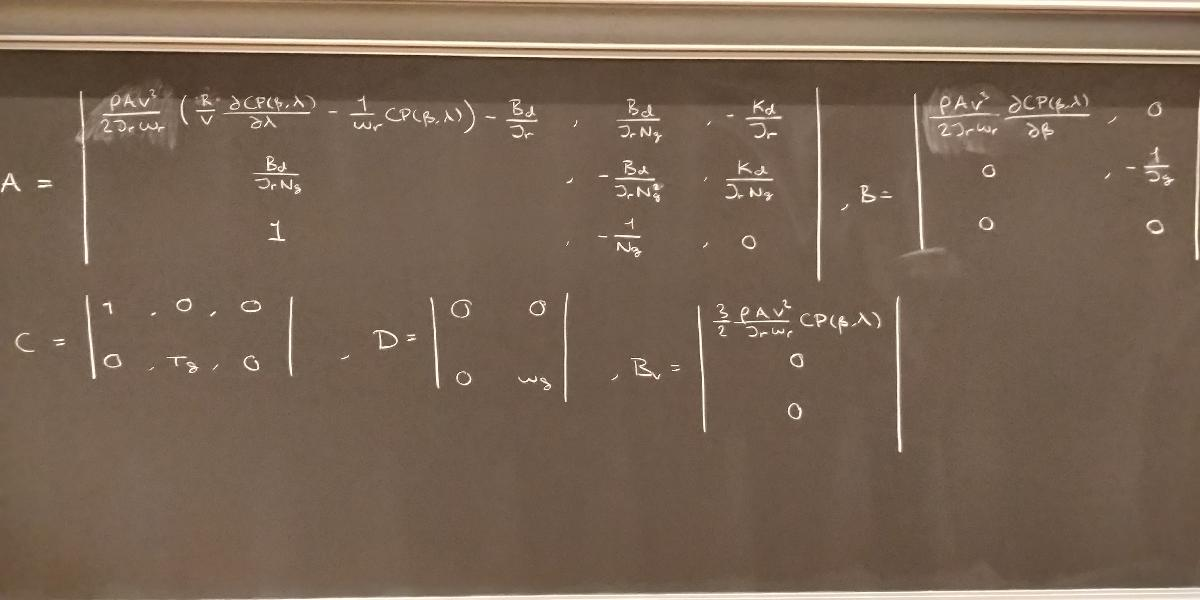 

When using *linmod() *one has to recall that the order of the input and output ports in the Simulink model is used as reference to sort the state and input vector. Hence the order must be the same as specified in **P1**. 

The disturbance $v_{OP}$ acts on the system hence $B_v$ has to be computed too. One can expand $u_{OP}$ to include the disturbance. Finally $B_v$ will be the last column of the output $B$ matrix from *linmod(). *

Moreover second and third rows in the C and D matrices have to be removed since the actual outputs are $\omega_r$ and $P_e$.

% For the numerical linearization use the Matlab function linmod
x0 = xOP; % update initial conditions
uOPDist = [uOP;v_OP]; % update the input vector
[Aa,Bb,Cc,Dd] = linmod('OpenLoopWindTurbineModelLinmod2015a',xOP,uOPDist);
% Find the actual B, C and D matrix. Also find Bv matrix.
Aa

Aa =    -0.0000    0.0000   -0.0015
    0.0120   -0.0001    1.6747
    0.0001   -0.0000         0


Bv = Bb(:,3)

Bv =     0.0209
         0
         0


Bb = Bb(:,1:2)

Bb =    -1.1066         0
         0   -0.0019
         0         0


Cc = Cc([1 4],:)

Cc =     1.0000         0         0
         0    0.0407         0


Dd = Dd([1 4],1:2)

Dd =          0         0
         0    0.1229


**P3    **Through simulation compare the state and output responses for step changes in the operating wind speed. Perform simulations for $\Delta v_{OP} = \pm0.5\,\mathrm{m/s}$ and for $\Delta v_{OP} = \pm2\,\mathrm{m/s}$ and discuss how well the linear model approximate the nonlinear dynamics.

**P3.Solution**

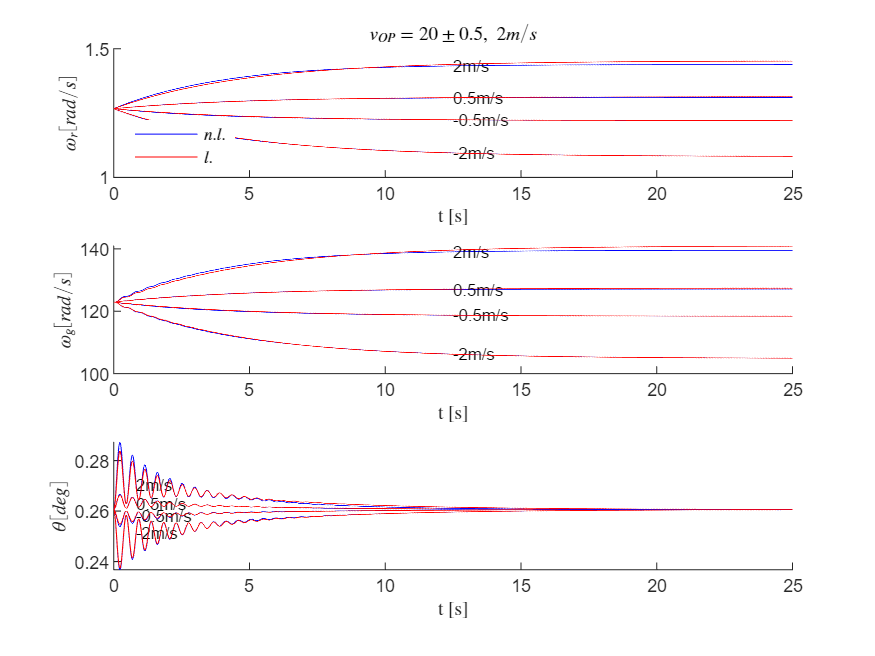

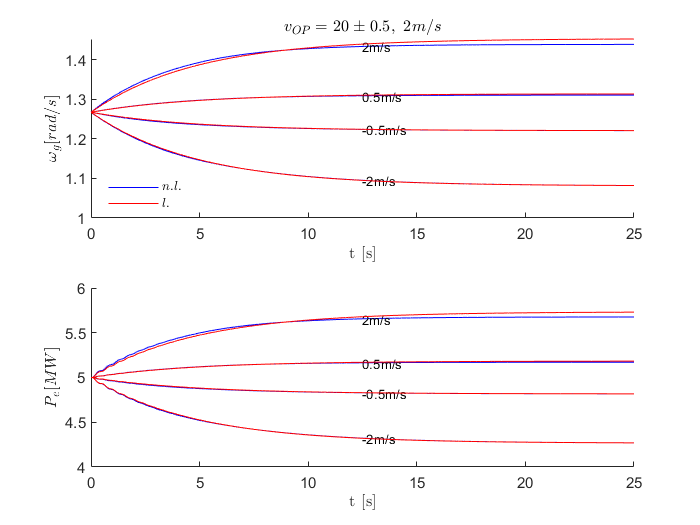

% Perform simulations around the operating point and plot the state and output responses
DU = [0;0];
TIME_SIM = 25; % Simulation Time updated
for Dv_OP = [-0.5 0.5 -2 2]
        figure(4)
        sim('OpenLoopWindTurbineModelLVsNL2015a')

        % non linear states and output
        x1 = yout(:,1);
        x2 = yout(:,2);
        x3 = yout(:,3);
        y1 = yout(:,1);
        y2 = yout(:,4);
        
        % linear states and output
        x1l = yout(:,5);
        x2l = yout(:,6);
        x3l = yout(:,7)*180/pi;
        y1l = yout(:,8);
        y2l = yout(:,9);
        
        subplot(3,1,1)
        hold on
        plot(tout,x1,'b')
        text(tout(floor(end/2)),x1(floor(end/2)),[num2str(Dv_OP) 'm/s'],'FontSize',8)
        plot(tout,x1l+xOP(1),'r')
        leg1 = legend('$n.l.$','$l.$','location','best');
        set(leg1,'Interpreter','latex');
        set(leg1,'FontSize',8);
        legend boxoff
        xlabel('t [s]','Interpreter','latex')
        ylabel('$\omega_r [rad/s]$','Interpreter','latex')
        title('$v_{OP} = 20 \pm 0.5, \ 2  m/s$','Interpreter','latex')
        hold off
        subplot(3,1,2)
        hold on
        plot(tout,x2,'b')
        text(tout(floor(end/2)),x2(floor(end/2)),[num2str(Dv_OP) 'm/s'],'FontSize',8)
        plot(tout,x2l+xOP(2),'r')
        xlabel('t [s]','Interpreter','latex')
        ylabel('$\omega_g [rad/s]$','Interpreter','latex')
        hold off
        subplot(3,1,3)
        hold on
        plot(tout,x3,'b')        
        text(tout(floor(end/30)),x3(floor(end/30)),[num2str(Dv_OP) 'm/s'],'FontSize',8)
        plot(tout,x3l+xOP(3)*180/pi,'r')
        xlabel('t [s]','Interpreter','latex')
        ylabel('$\theta [deg]$','Interpreter','latex')
        hold off
        
        figure(5)
        subplot(2,1,1)
        hold on
        plot(tout,y1,'b')
        text(tout(floor(end/2)),y1(floor(end/2)),[num2str(Dv_OP) 'm/s'],'FontSize',8)
        plot(tout,y1l+xOP(1),'r')
        leg1 = legend('$n.l.$','$l.$','location','best');
        set(leg1,'Interpreter','latex');
        set(leg1,'FontSize',8);
        legend boxoff
        xlabel('t [s]','Interpreter','latex')
        ylabel('$\omega_g [rad/s]$','Interpreter','latex')
        title('$v_{OP} = 20 \pm 0.5, \ 2  m/s$','Interpreter','latex')        
        hold off
        subplot(2,1,2)
        hold on
        plot(tout,y2,'b')
        text(tout(floor(end/2)),y2(floor(end/2)),[num2str(Dv_OP) 'm/s'],'FontSize',8)
        plot(tout,y2l+Pe_OP/1e6,'r')
        xlabel('t [s]','Interpreter','latex')
        ylabel('$P_e [MW]$','Interpreter','latex')
        hold off
end

The model responds similarly to the variation in the wind speed though the larger the variation the less accurate the linear model compared to the non linear one.

**P4    **Sweep the wind speed in the range $v_{OP} \in \left[18, 25\right] \, \mathrm{m/s}$ and assess how the eigenvalues of the linear model vary in relation to changes in the operating wind speed. What conclusion can be reached about the stability of the origin of the linear model?

**P4.Solution**

It is assumed, that the rated power and angular velocity stay the same. The eigenvalues as a function of varying windspeed can be found by repeated use of trim and linmod at the different windspeeds. A possible way of finding it numerically is shown below:

% For each operating wind speed in the given range the system dynamical matrix A needs to be recomputed.
v_OP_step = 0.2;
vVector = 18:v_OP_step:25;
ev = zeros(length(vVector),3);
for i = 1:length(vVector)
    v_OPn = 18+(i-1)*v_OP_step;
    xOP_0 = [omega_r_OP;omega_g_OP;theta_Op];
    uOP_0 = [Beta_OP_rad;Tg_OP;v_OPn];
    yOP_0 = [omega_r_OP; omega_g_OP;theta_Op;5];
    
    x0 = xOP_0;% Integrators initial conditions
    format short g
    [xOP,uOP]=trim('OpenLoopWindTurbineModelLinmod2015a',xOP_0,uOP_0,yOP_0,[],[],[1 1]);
    [Aol,~,~,~] = linmod('OpenLoopWindTurbineModelLinmod2015a',xOP,uOP);
    ev(i,:) = eig(Aol);
end

Looking at the eigenvalues we have one real and a complex conjugated eigenvalue pair. The imaginary part of the complex eigenvalue does not change with varying windspeed. Hence only the real part is plotted below.

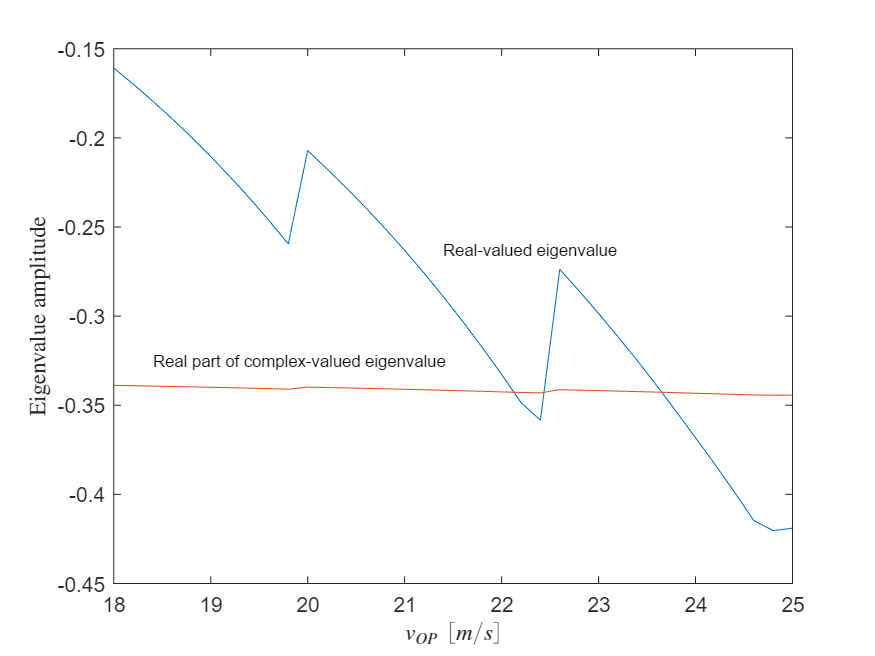

figure(6)
plot(vVector,ev(:,1))
hold on
plot(vVector,real(ev(:,2))*0.5) % The real part of the second eigenvalue is scaled to better visualize it
xlabel('$v_{OP} \ [m/s]$','Interpreter','latex')
ylabel('Eigenvalue amplitude','Interpreter','latex')
text(vVector(floor(end/2)),ev(floor(end/2),1)/1.1,'Real-valued eigenvalue','FontSize',8)
text(vVector(floor(end/10)),ev(floor(end/2),2)/2.1,'Real part of complex-valued eigenvalue','FontSize',8)

**P5   **Set the wind speed at $v_{OP} = 20\,\mathrm{m/s}$ and compute the modal matrix. Write the state response as the linear combination of the eignemodes of the system and determine which eigenmode is dominant in each of the state variables.

**P5.solution**

% The modal matrix can be found by using the Matlab function eig
[M,lbd,~] = eig(Aa);
% time constants
lbd = diag(lbd);
tau = -1./lbd(imag(lbd)==0)

tau =        4.8291



% natural frequencies and damping ratios
wn = sqrt(real(lbd(2))^2+imag(lbd(2))^2)

wn =        13.686


z = -real(lbd(2))/wn

z =      0.049661



% Make Modal Matrix real
lbd = diag(lbd);
[M,~] = cdf2rdf(M,lbd)

M =    -0.0103   -0.0012   -0.0000
   -0.9999    1.4142         0
    0.0000    0.0001    0.0012


$\omega_r$ is influenced mainly by the first eigenmode because -0.0103 is two and three orders of magnitude bigger than -8.7e-4 and  -1.43e-5 respectively.

$\omega
_g$ is mainly influenced by the first eigenmode and from the real part of the complex pair. The imaginary part has no effect.

 $\theta$ is mainly influenced by the imaginary part of the complex pair. Again 8.16e-4 is 3 orders of magnitude bigger than 1.238e-5 and 3.953e-5.

Overall the analysis confirms what is seen in **Problem 3. **

Firstly $\omega_r(t)$does not exhibit any oscillation. This is due to the fact that only the real eigenvalues contributes mainly to the response. Secondly $\omega_g(t)$ is slightly oscillatory during the transient phase probably because the complex eigenmode is weighted less than the real one in the partial fractions decomposition.

Finally $\theta(t)$ shows more evident oscillations because of the complex eigenmode.

Now let us derive the partial fraction decomposition of the *States *transfer function matrix. For that reason let us assume $C$ and $D$ to be the $I^3$ and $0^{3, 1}$ matrices respectively. 

$B = B_v$ since so far we studied the response of the system provided some $\Delta v_{OP}$. Each state is then caracterized by a single transfer function.

Cn = eye(3);
Dn = zeros(3,1);

% Transfer Function Matrix v (Disturbance) -> X (states)
sysn = ss(Aa,Bv,Cn,Dn);
Gs = minreal(tf(sysn));

% Find Constant residuals matrix
syms ax bx c1 s
lbd = diag(lbd);
Pol = c1*(s^2+2*z*wn*s+wn^2)+(ax*(s-real(lbd(2)))+bx*abs(imag(lbd(2))))*(s-lbd(1));
Pol = expand(Pol);
Pol = vpa(Pol);


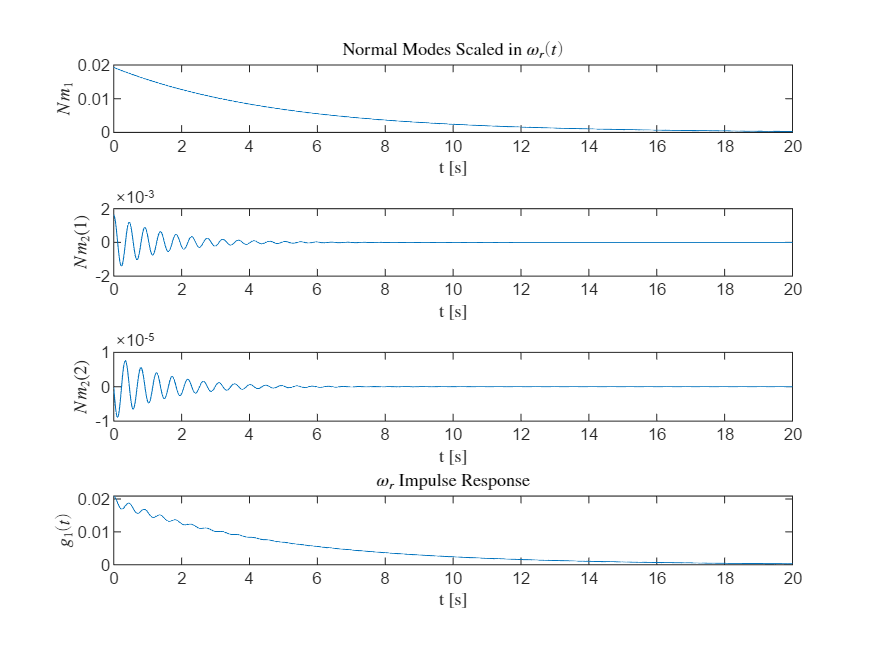

% Omega_r
CfRes = coeffs(Pol,s);
CfTf = fliplr(Gs.Numerator{1}(2:end));

eqn1 = CfRes(1) - CfTf(1);
eqn2 = CfRes(2) - CfTf(2);
eqn3 = CfRes(3) - CfTf(3);

sol = solve([eqn1 == 0,eqn2 == 0,eqn3 == 0],[c1 ax bx]);

% Plot Natural Modes Weighted by the constant residuals
t= 0:0.01:20;
t2 = 0:0.01:20;

Nm2 = [sol.ax*exp(real(lbd(2))*t2).*cos(abs(imag(lbd(2)))*t2)
      sol.bx/abs(imag(lbd(2)))*exp(real(lbd(2))*t2).*sin(abs(imag(lbd(2)))*t2)]; 
Nm = sol.c1*exp(lbd(1)*t);

figure(7)
subplot(4,1,1)
plot(t,Nm)
hold on
title('Normal Modes Scaled in $\omega_r(t)$','Interpreter','latex')
xlabel('t [s]','Interpreter','latex')
ylabel('$ Nm_1$','Interpreter','latex')
hold off
subplot(4,1,2)
plot(t2,Nm2(1,:))
hold on
xlabel('t [s]','Interpreter','latex')
ylabel('$ Nm_2$(1)','Interpreter','latex')
hold off
subplot(4,1,3)
plot(t2,Nm2(2,:))
hold on
xlabel('t [s]','Interpreter','latex')
ylabel('$Nm_2$(2)','Interpreter','latex')
hold off
subplot(4,1,4)
plot(t2,Nm+Nm2(1,:)+Nm2(2,:))
hold on
title('$\omega_r$ Impulse Response','Interpreter','latex')
xlabel('t [s]','Interpreter','latex')
ylabel('$g_1(t)$','Interpreter','latex')
hold off

$\omega_r(t)$ impulse response reflects what stated above, i.e that the response is mainly influenced by the real eigenmode. Still the complex conjugate pair exerts some influence. But it is limited due to the magnitude of the corresponding eigenmodes.

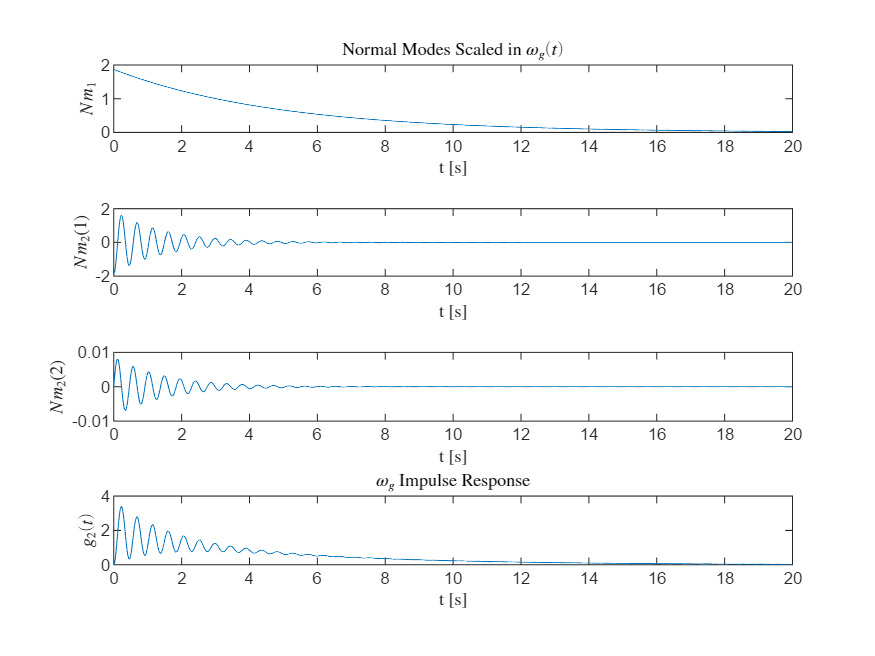

% Omega_g
CfTf = fliplr(Gs.Numerator{2}(2:end));

eqn1 = CfRes(1) - CfTf(1);
eqn2 = CfRes(2) - CfTf(2);
eqn3 = CfRes(3) - CfTf(3);
sol = solve([eqn1 == 0,eqn2 == 0,eqn3 == 0],[c1 ax bx]);

% Plot Natural Modes Weighted by the constant residuals
t= 0:0.01:20;
t2 = 0:0.01:20;

Nm2 = [sol.ax*exp(real(lbd(2))*t2).*cos(abs(imag(lbd(2)))*t2)
      sol.bx/abs(imag(lbd(2)))*exp(real(lbd(2))*t2).*sin(abs(imag(lbd(2)))*t2)]; 
Nm = sol.c1*exp(lbd(1)*t);

figure(8)
subplot(4,1,1)
plot(t,Nm)
hold on
title('Normal Modes Scaled in $\omega_g(t)$','Interpreter','latex')
xlabel('t [s]','Interpreter','latex')
ylabel('$ Nm_1$','Interpreter','latex')
hold off
subplot(4,1,2)
plot(t2,Nm2(1,:))
hold on
xlabel('t [s]','Interpreter','latex')
ylabel('$ Nm_2$(1)','Interpreter','latex')
hold off
subplot(4,1,3)
plot(t2,Nm2(2,:))
hold on
xlabel('t [s]','Interpreter','latex')
ylabel('$Nm_2$(2)','Interpreter','latex')
hold off
subplot(4,1,4)
plot(t2,Nm+Nm2(1,:)+Nm2(2,:))
hold on
title('$\omega_g$ Impulse Response','Interpreter','latex')
xlabel('t [s]','Interpreter','latex')
ylabel('$g_2(t)$','Interpreter','latex')
hold off

$\omega_g(t)$ is equally influenced by the real eigenmode and the real part of the complex eigenmode. In fact their magnitude is comparable at the beginning of the time horizon. The contribute of the imaginary part is two order of magnitude smaller.

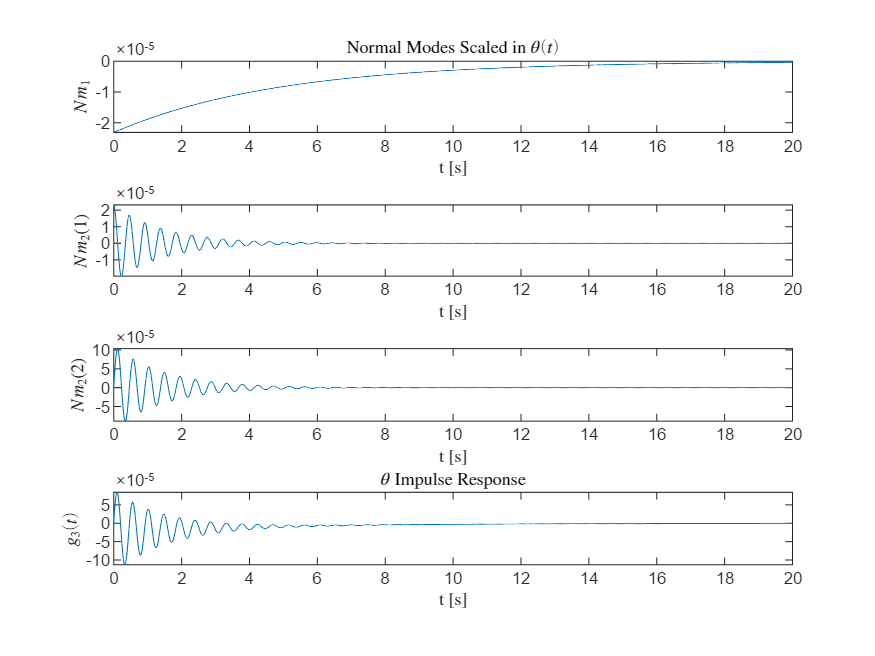

% Theta
CfTf = fliplr(Gs.Numerator{3}(2:end));

eqn1 = CfRes(1) - CfTf(1);
eqn2 = CfRes(2) - CfTf(2);
eqn3 = CfRes(3) - CfTf(3);
sol = solve([eqn1 == 0,eqn2 == 0,eqn3 == 0],[c1 ax bx]);

% Plot Natural Modes Weighted by the constant residuals
t= 0:0.01:20;
t2 = 0:0.01:20;

Nm2 = [sol.ax*exp(real(lbd(2))*t2).*cos(abs(imag(lbd(2)))*t2)
      sol.bx/abs(imag(lbd(2)))*exp(real(lbd(2))*t2).*sin(abs(imag(lbd(2)))*t2)]; 
Nm = sol.c1*exp(lbd(1)*t);

figure(9)
subplot(4,1,1)
plot(t,Nm)
hold on
title('Normal Modes Scaled in $\theta(t)$','Interpreter','latex')
xlabel('t [s]','Interpreter','latex')
ylabel('$ Nm_1$','Interpreter','latex')
hold off
subplot(4,1,2)
plot(t2,Nm2(1,:))
hold on
xlabel('t [s]','Interpreter','latex')
ylabel('$ Nm_2$(1)','Interpreter','latex')
hold off
subplot(4,1,3)
plot(t2,Nm2(2,:))
hold on
xlabel('t [s]','Interpreter','latex')
ylabel('$Nm_2$(2)','Interpreter','latex')
hold off
subplot(4,1,4)
plot(t2,Nm+Nm2(1,:)+Nm2(2,:))
hold on
title('$\theta$ Impulse Response','Interpreter','latex')
xlabel('t [s]','Interpreter','latex')
ylabel('$g_3(t)$','Interpreter','latex')
hold off

Finally the impulse response of $\theta(t)$. As already seen in the modal matrix the imaginary part of the complex pair plays the most relevant role.

**P6**    Determine a suitable sampling time for the linear system and discretize the linear model. Compute the eigenvalues of the discrete time linear model and use Frobenius theorem to show the equivalence with the eigenvalues of the continuous time linear system.

**P6.Solution**

To choice of a suitable samping time depends on the fastest dynamics that has to be captured.

The time constant refers to the transient phase of the real eigenmode. 

The period $T = 2\cdot \pi/\omega_n$ deals with the time interval such that the imaginary and the real parts of the complex pair repeats.

The sampling time is chosen 10 time smaller than the smaller between $T$ and $\tau$.

% To discretize the continuous time linear system use the Matlab function c2d
T = 2*pi/wn;
if T < tau(1)
    Ts = tau(1)/10;
else 
    Ts = T/10;
end
[Ff,Gg] = c2d(Aa,Bb,Ts) %discretize the LTIC

Ff =     0.8862    0.0002   -0.2381
   21.0086    0.6916  276.0987
    0.0162   -0.0002    0.6953


Gg =    -0.4701   -0.0000
  -43.8580   -0.0001
   -0.0013    0.0000


lbd_d = eig(Ff) %find the discrete eigenvalues

lbd_d =    0.9048 + 0.0000i
   0.6841 + 0.2251i
   0.6841 - 0.2251i


lbd_d_calc = exp(Ts*lbd) %apply Frobenius theorem

lbd_d_calc =    0.9048 + 0.0000i
   0.6841 + 0.2251i
   0.6841 - 0.2251i
